clear, close all, clc

Anvender data fra opgave 11-10.

load('dataset_problem_11_10.mat')

Opgave a)

Hvor meget af variationen forklares med regressionen? (Altså, find R^2)

X = [data(:,2) linspace(1,1,max(size(data)))'];
y = data(:,1)

y =     4.4000
    6.6000
    9.7000
   10.6000
   10.8000
   10.9000
   11.8000
   12.1000
   14.3000
   14.7000


[b,~,r,~,STATS] = regress(y,X)

b =    20.5673
    0.4705


r =     0.0217
    3.0444
   -2.4938
   -4.2676
   -3.4506
   -2.5279
    1.6629
   -2.7676
    1.4892
   -1.8130


STATS =     0.8522   92.2239    0.0000   13.8092


R2 = STATS(1)

R2 = 0.8522

% R^2 er altså 0.8522

Opgave b)

Plot residualerne mod y_hat og x.

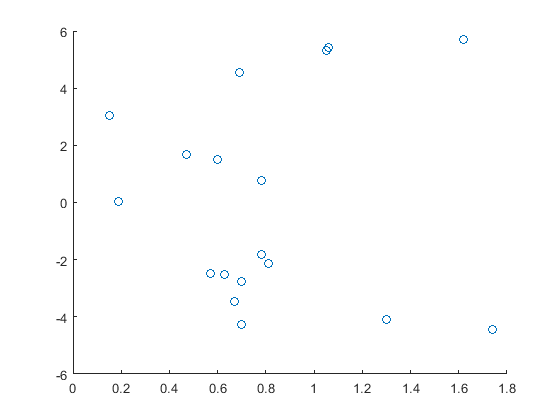

scatter(data(:,2),r)

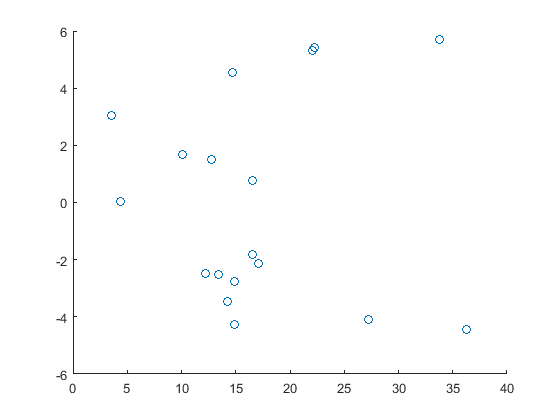

scatter(b(1)*data(:,2)+b(2),r)

% Residualerne ser korrekt fordelt ud omkring 0,
% men ser ud til at blive større med x og y_hat

Opgave c)

Lav et normalfordelingsplot af residualerne. Ser de normalfordelte ud?

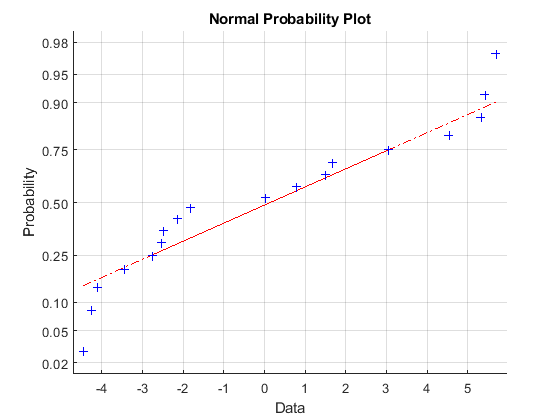

normplot(r)

% Halerne ser forkerte ud, men resten er okay.